# 13 Linear Programming: The Simplex Method

The **standard form **of a linear program is


$$\left.\begin{array}{lll}\min & c^T x\\ \text{subject to} & \\ & Ax =b \\ & x\geq 0\end{array}\qquad \right\} (LP)$$


- $c, x \in \mathbb{R}^n$, 

- $b \in \mathbb{R}^m$,

- $n$ number of variables, $m$ is the number of constraints.

- $A \in \mathbb{R}^{m\times n}$ ( We assum that $A$ has full rank and $m < n$)

% rng("default")
% A = randi([-3,4],4,4);
% A(4,:) = A(3,:);
% [Q,R,U] = qr(A)
% Q(:,1:3)*R(1:3,:)


**Other forms can be transformed into this form**

- $\min c^Tx, \text{ subject to } Ax \leq b$, we add *slack variables.*

- $\min c^Tx, \text{ subject to } Ax \geq b$, $x\geq 0$ we subtract *slack variables (add surplus).*

- $\min c^Tx, \text{ subject to } Ax = b, x\leq u$, we add *slack variables.*

The feasible set of (LP) is defined as 


$$\Omega =\{x\in \mathbb{R}^n | Ax=b, x\geq 0\}$$
 

- We say that the linear program (LP) is **infeasible** if the feasible set is empty. 

- If $\Omega = \emptyset$, (LP) has no solution

- $\Omega$ is a convex set.

- We say that the problem (LP) is **unbounded** if the objective function is unbounded below on the feasible region, that is, there is a sequence of points $x_ k$ feasible for (LP) such that $c^T x_k \downarrow  -\infty $. (Of course, unbounded problems have no solution).

- If (LP) is bounded and feasible, it can have one solution or infinitely many solution.

#### OPTIMALITY CONDITIONS 

The Lagrangian function of (LP) is 


$$\mathcal{L}(x,\lambda,s) = c^Tx - \lambda^T(Ax-b) - s^Tx$$


The first order optimality conditions, KKT, (Theorem 12.1)  gives that if $x^*$ is an optimal feasible solution to (LP), then there exist $\lambda \in \mathbb{R}^m$ and $s\in\mathbb{R}^n$ such that


$$\begin{array}{rll}A^T\lambda + s &=& c \\ Ax &=& b \\ x &\geq& 0 \\ s&\geq&0 \\ s_ix_i &=&0, i=1,\cdots n\end{array}$$


- These conditions are also sufficient. 

- For a vector triple $(x^*, \lambda^*,s^*)$ that satisfy these conditions, we have $c^Tx^*=b^T\lambda^*$

- The feasible point $\bar{x}$ is optimal if and only if  $\bar{x}^T s^\ast  = 0$,

#### THE DUAL PROBLEM

The dual problem for (LP) is defined as 


$$\max b^T\lambda, \text{ subject to } A^T\lambda \leq c \quad (\text{DLP})$$


This can be rewritten as 


$$\max b^T\lambda, \text{ subject to } A^T\lambda + s = c, s\geq 0$$


- (LP) is called the primal problem

- The primal–dual relationship is symmetric

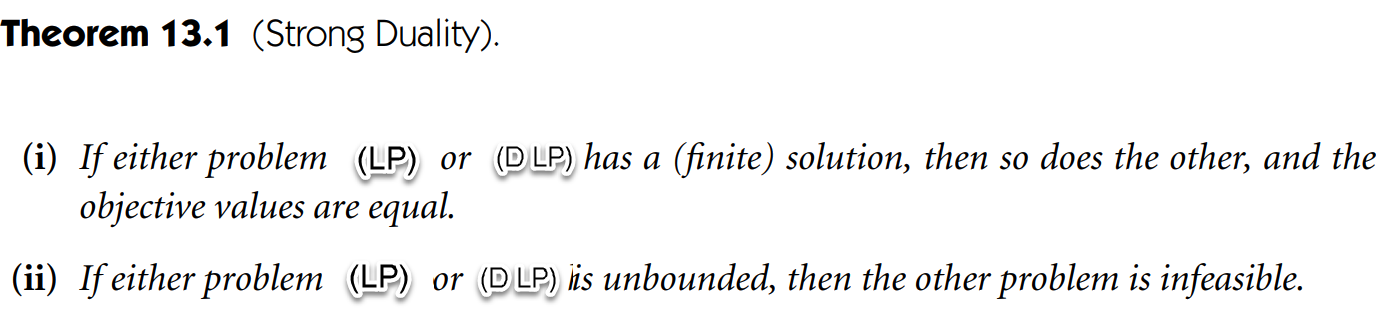

Remark

- The multiplier values λ and $s$ indicate the sensitivity of the optimal objective value to perturbations in the constraints. In fact, the process of finding (λ,s) for a given optimal x is often called **sensitivity analysis**

#### 13.2 GEOMETRY OF THE FEASIBLE SET

**Definitions**

▶ A vector $x\in\mathbb{R}^n$ is called ***basic feasible point*** of (LP) if 

        1️⃣ it is feasible ($Ax=b, x\geq 0$) and 

        2️⃣ there is a subset $\mathfrak{B}$ of $\{1,2,\cdots,n\}$ such that

                a. $\mathfrak{B}$ contains exactly $m$ indices,

                b. $i\not\in\mathfrak{B}$ implies that $x_i=0$  (that is, the bound $x_i \ge  0$ can be inactive only if $i \in  \mathfrak{B}$);

                c. The $m\times m$ matrix $B$ defined by $B=[A_i]_{i\mathfrak{B}}$, ($A_i$ is the ith column of $A$) is nonsingular.

▶ A set $\mathfrak{B}$ satisfying the above is called **basis **for (LP)

▶ The matrix $B$ is called the **basis matrix.**

▶ A vector $x\in\mathbb{R}^n$ is called ***basic optimal point*** of (LP) if it is a solution of (LP) and also a basic  feasible point. 

▶ **(Degeneracy)**. A basis $\mathfrak{B}$ is said to be **degenerate** if $x_i=0$ for some $i \in  \mathfrak{B}$, where $x$ is the basic feasible solution corresponding to $\mathfrak{B}$. A linear program (LP) is said to be **degenerate** if it has at least one degenerate basis.

**Theorem 13.2 (***fundamental theorem of linear programming***)**

- If (LP) has a nonempty feasible region, then there is at least one basic feasible point; 

- If (LP) has solutions, then at least one such solution is a basic optimal point. 

- If (LP) is feasible and bounded, then it has an optimal solution.

#### VERTICES OF THE FEASIBLE POLYTOPE

- The feasible set defined by the linear constraints is a ***polytope***, and 

- the **vertices** of this polytope are the points that do not lie on a straight line between two other points in the set.

- Algebraically, the **vertices** are exactly the **basic feasible points** defined above.           

**Theorem 13.3. **

All basic feasible points for (LP) are vertices of the feasible polytope $\{x | Ax =b, x \ge  0\}$, and vice versa.

#### 13.3 THE SIMPLEX METHOD (*revised simplex method*)

**Remarks (to simplify)**

- A point $x$ is a basic feasible point (or a vertex of feasible polytope) if it is feasible and is not a linear combination of any other feasible points.

- If (LP) has solutions, at least one solution is a basic feasible solution. (Theorem 13.2)

- At a basic feasible point, at least $n-m$ variables are zero. The case it has more than $n-m$ zero variables is called degenerate.

- All iterates of the simplex method are basic feasible points for (LP) and therefore vertices of the feasible polytope.

- Most steps consist of a move from one vertex to an adjacent one for which the basis $\mathfrak{B}$ differs in exactly one component.

-  On most steps (but not all), the value of the primal objective function $c^Tx$ is decreased.

- The major issue at each simplex iteration is to decide which index to remove from the basis $\mathfrak{B}$.

Let $\mathcal{N}$ be the index set of **nonbasic **variables.  $\mathcal{N}=\{1,\cdots,n\} \setminus \mathfrak{B}$ ( $x_i=0, i\in\mathcal{N}$ )

- $B=[A_i]_{i\in\mathfrak{B}}$, $N=[A_i]_{i\in\mathcal{N}}$

- 
$$x_B=[x_i]_{i\in\mathfrak{B}}, \quad x_N=[x_i]_{i\in\mathcal{N}}$$


- 
$$s_B=[s_i]_{i\in\mathfrak{B}}, \quad s_N=[s_i]_{i\in\mathcal{N}}$$


- 
$$c_B=[c_i]_{i\in\mathfrak{B}}, \quad c_N=[c_i]_{i\in\mathcal{N}}$$


So, we have

$Ax = Bx_B + Nx_N = b$,  

For each iteration $x_N=0$, hence $x_B = B^{-1}b$ 

Assuming nondegenercy we set $s_B=0$ and so  $s^Tx=0$

We find $\lambda$ and $s_N$ from $B^T\lambda = c_B$ and $N^T\lambda +s_N = c_N$

That is 

- 
$$\lambda = B^{-T}c_B$$


- $s_N = c_N - (B^{-1}N)^T c_B$       (pricing)  components of $s_N$ are called reduced cost of $x_N$.

- if $s_N\geq 0$ we have found the optimal $(x,\lambda,s)$

- if one component or more of $s_N$ is negative, we choose one index $q\in\mathcal{N}$ where $s_q<0$

- this index $q$ is called the **entering index**. It enters $\mathfrak{B}$.

- it turns out that $c^Tx$ descreases when we allow $x_q$ to increase away from zero iff (1) $s_q<0$ and (2) it is possible to increase $x_q$ away from zero while maintaining feasibility of $x$

Changing $\mathfrak{B}$ (pivoting)

- allow $x_q$ to increase from zero during the next step. 

- fix all other components of $x_N$ at zero, and figure out the effect of increasing $x_q$ on the current basic vector $x_B$ , given that we want to stay feasible with respect to the equality constraints $Ax= b$.

- keep increasing $x_q$ until one of the components of $x_B$ ( $x_p$, say ) is driven to zero, or determining that no such component exists (the unbounded case).

- remove index $p$ (known as the **leaving index**) from $B$ and replace it with the entering index $q$.

To be more precise, let $x^+$ be the next iterate and $x$ is the current.

    $q\in \mathcal{N}$ is the entering index, so $x_q^+>0$

since $x^+$ and $x$ must be feasible then 

    $Ax^+ = Bx^+_B + A_qx^+_q = b$  and

    
$$Ax = Bx_B =b$$


Therefore,

$Bx^+_B + A_qx^+_q =Bx_B$ and $x_B^+ = x_B - B^{-1}A_qx_q^+$

Geometrically speaking, we are moving along an edge of the feasible polytope that decreases $c^T x$.

- as we increase $x^+_q$, one component $x^+_p$ becomes zero and so we remove it from the basis and replace it with $x_q$.

This affects the cost function


$$c^Tx^+ = c^Tx_B^+ + c_qx_q = c^Tx_B-c^T_BB^{-1}A_q x_q^+ + c_qx^+_q$$


       $=c^Tx_B-\lambda^TA_q x_q^+ + c_qx^+_q$   (since $\lambda = B^{-T}c^T_B$)

       $=c^Tx_B-(c_q-s_q)x_q^+ + c_qx^+_q$   (since $\lambda^TA_q + s_q = c_q$ and $\lambda^TA_q =c_q-s_q$ )

       
$$=c^Tx_B + s_qx_q^+$$


Since $s_q<0$ , this step produces a decrease in $c^Tx$ provided that $x_q>0$.

if $x_B^+ = x_B - B^{-1}A_qx_q^+\geq 0$ for all positive $x_q$ , the problem is unbounded.

**Theorem 13.4.** 

Provided that the linear program (LP) is **nondegenerate** and bounded, the simplex method terminates at a basic optimal point.

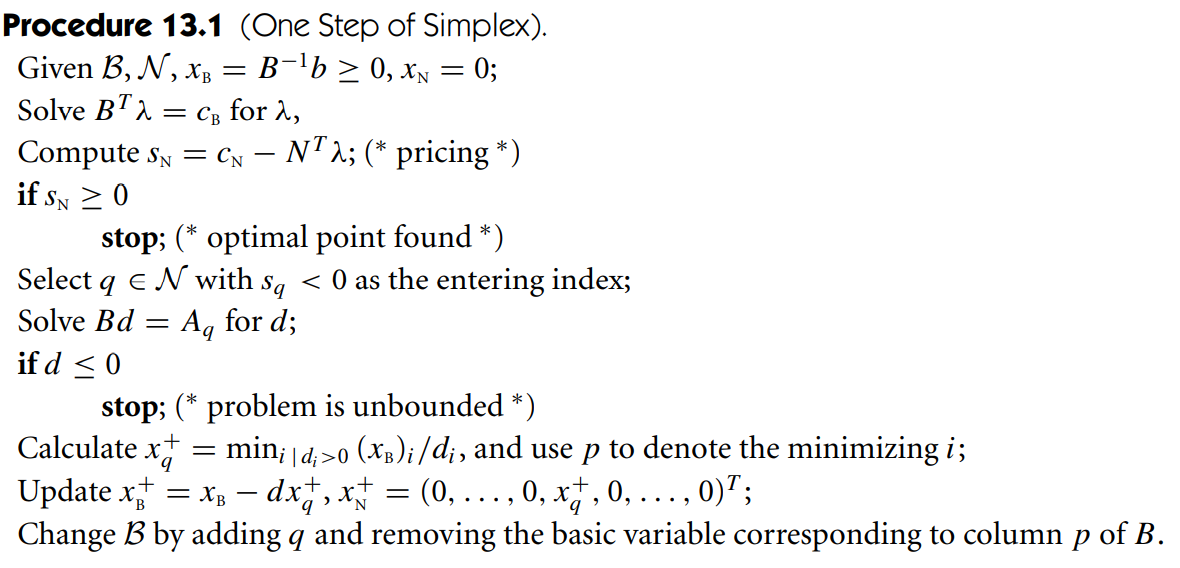

clearvars
A = [1 1 1 0;2 0.5 0 1];
b=[5;8];
c = [-4;-2;0;0];
f = @(x) c'*x;
% first iteration
BB = [3,4];
NN = [1,2];
B = A(:,BB);
N = A(:,NN);
cB = c(BB);
cN = c(NN);
xB = B\b;
lambda = B'\cB;
sN = cN - N'*lambda;
q = 1;
d = B\A(:,q);
[~,ind]=min(xB./d);
p = BB(ind);

% second iteration
BB = [3,1];
NN = [4,2];
B = A(:,BB);
N = A(:,NN);
cB = c(BB);
cN = c(NN);
xB = B\b;
lambda = B'\cB;
sN = cN - N'*lambda;
q = 2;
d = B\A(:,q);
[~,ind]=min(xB./d);
p = BB(ind);


% third iteration
BB = [2,1];
NN = [4,3];
B = A(:,BB);
N = A(:,NN);
cB = c(BB);
cN = c(NN);
xB = B\b

xB =     1.3333
    3.6667


lambda = B'\cB

lambda =    -1.3333
   -1.3333


sN = cN - N'*lambda

sN =     1.3333
    1.3333


f([xB(2) xB(1) 0 0]')

ans = -17.3333

#### Complexity 

- In each iteration, the most time consuming task is **pricing**, **ratio test** and update $B$. $O(mn)$ 

- The number of iterations is less than or equals to the number of basic feasible points, which is $\left(\begin{array}{c}n\\m\end{array}\right)=\frac{n!}{(n-m)!m!}$ 

- The worst case time complexity is **exponential**.   $n=2m$. The number of iterations $> 2^m$. 

- But practically, it terminates in $m$ to $3m$ iterations. 

#### Remaining problems

🔵 How to find the initial basic feasible point? 

- Two phase algorithm: add more slack variables to make the trivial point (0,…,0) feasible, and solve it until all additional slack variables become zero. 

🔵 How to resolve the degenerate case? 

- In degenerate case, the algorithm might pivot the same $p$ and $q$ repeatedly. 

- Perturb the constraints to avoid the degenerate case.

% i trick
f = @(x) exp(x)/sqrt((sin(x))^3+(cos(x))^3);
g = @(f,x) imag(f(x+1i*1e-30))/1e-30;


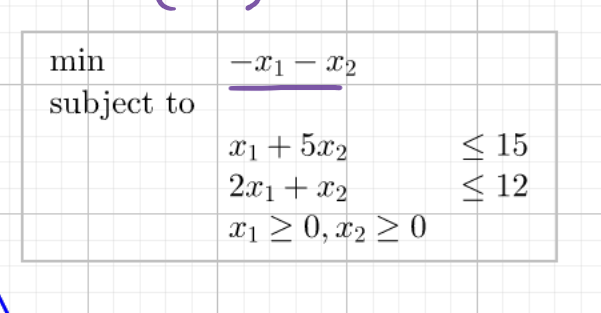

% c = [-1;-1];
% A = [1 5;2 1];
% b = [15;12];
% lb = [0;0];
% ub = [];
% options = optimoptions('linprog','Algorithm','interior-point');
% [x,fval,exitflag,output,lambda] = linprog(c,A,b,[],[],lb,[],options)
% lambda.lower
% lambda.upper
% lambda.ineqlin
fun = @(x) 100*(x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [-1.2,1];
x = fminunc(fun,x0)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =     1.0000    1.0000
